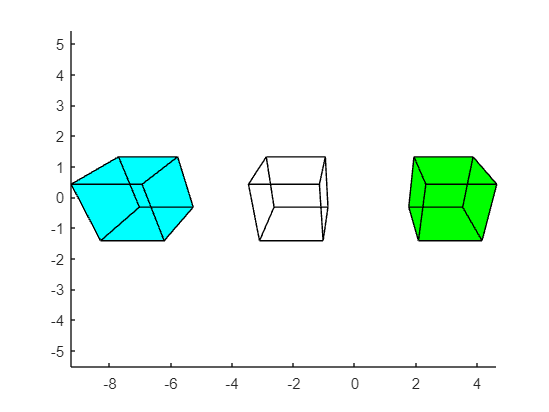

verticesCube1 = [
    -1, 1, 1, -1, -1, 1, 1, -1;
    -1, -1, 1, 1, -1, -1, 1, 1;
    -1, -1, -1, -1, 1, 1, 1, 1;
    1, 1, 1, 1, 1, 1, 1, 1
    ];

move1Cube = [
    1, 0, 0, 5;
    0, 1, 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];

move2Cube = [
    1, 0, 0, 10;
    0, 1, 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];


verticesCube2 = move1Cube * verticesCube1;
verticesCube3 = move2Cube * verticesCube1;

facesCube = [
    1, 2, 6, 5;
    2, 3, 7, 6;
    3, 4, 8, 7;
    4, 1, 5, 8;
    1, 2, 3, 4;
    5, 6, 7, 8
    ];

move1 = [
    1, 0, 0, 7;
    0, 1, 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1;
    ];


phi1 = pi/6;
rotateXMatrix = [
    1, 0, 0, 0;
    0, cos(phi1), -sin(phi1), 0;
    0, sin(phi1), cos(phi1), 0;
    0, 0, 0, 1
    ];
tpr = [
    1, 0, 0, 0;
    0, 1, 0, 0;
    0, 0, 0, 0;
    0, 0, 0, 1
    ];
tp = [
    1, 0, 0, 0;
    0, 1, 0, 0;
    0, 0, 1, 0;
    0, 0, 0.1, 1
    ];
t = tpr * tp;

nv1 = (rotateXMatrix * move1)^(-1) * verticesCube1;
nv2 = (rotateXMatrix * move1)^(-1) * verticesCube2;
nv3 = (rotateXMatrix * move1)^(-1) * verticesCube3;

DrawShape (t*nv1, facesCube, 'c')
DrawShape (t*nv2, facesCube, 'w')
DrawShape (t*nv3, facesCube, 'g')

axis equal;
view(0, 90);

%view(3);


function DrawShape(vertices, faces, color)
    patch('Vertices', (vertices(1:3,:)./vertices(4,:))','Faces', faces, 'FaceColor', color);

end